# **Abschluss Projekt: Mars**

clear all

**Laden von Konstanten**

Zu Beginn des Codes werden wichtige Konstanten wie der Erdradius, die Erdmasse, die Sonnenmasse und andere relevante Werte aus einer externen Datei (`data/constants.mat`) geladen. Diese Konstanten sind entscheidend für die Berechnungen der Trajektorie der Sonde und umfassen beispielsweise die Anfangsgeschwindigkeit der Sonde und den Abstand der Erde von der Sonne.

load('data/constants.mat');

**Model Sonnensystem**

Für die Berechnung der Trajotery der Sonde wird ein Modell des Sonnensystems benötigt. *modelSolarSystem.m* erstellt eine Animation des Sonnensystems *positionsCalcPlanets.m *dagegen, nimmt eine Zeitpunkt und gibt die Position von Erde und Mars zurück.

Die Umlaufbahnen werden aus den in *constants.mat* gespreicherten Umlaufzeiten von Erde und Mars sowie deren Bahnradien (vereinfacht zu einem Kreis) wie folgt berechnet:

$\omega = \frac{2\pi}{T}$ mit $T = Umlaufzeit$


$$\theta = \omega * t$$


$x = r * sin(\theta)$ mit $r=Bahnradius$

$y=r * cos(\theta)$ mit $r=Bahnradius$

%modelSolarSystem(constants);

**Umrechnung der Simulationszeit**

Die vorgegebene Simulationszeit ist in Tagen angegeben. Diese wird in Sekunden umgerechnet, da die ODE-Lösung (Ordinary Differential Equations) in der Regel eine Zeiteinheit in Sekunden benötigt. Die Umrechnung erfolgt durch Multiplizieren mit der Anzahl der Stunden pro Tag (24) und der Anzahl der Sekunden pro Stunde (3600).

tSpan = [0, constants.simulationTime *24 * 3600];

**Festlegung der Anfangsbedingungen**

Die Anfangsbedingungen für die Simulation der Sonde werden definiert. Die Position der Sonde wird zu Beginn auf der Erdumlaufbahn gesetzt, wobei der Abstand von der Erde zur Sonne durch die Summe des Erdradius und des Abstands der Erde von der Sonne bestimmt wird. Die Anfangsgeschwindigkeit der Sonde setzt sich aus der Geschwindigkeit der Erde und der zusätzlichen Geschwindigkeit, die für die Mission erforderlich ist, zusammen.

pos0 = [constants.earthOrbitRadius + constants.earthRadius, 0, 0, constants.probeIntialVelocity + constants.earthVelocity];

**Defenieren der Differentialgleichung**

Um die Flugbahn der Sonde zu berechnen, wird eine Differentialgleichung benötigt.


$$\frac{dr}{dt} = v$$



$$\frac{dv}{dt} = a = - \frac{GM_{\text{sonne}}}{|\vec{r}|^3}\vec{r}$$


Defeniert wird die differntial Gleichung in dem Vektor $u$:


$$\vec{u} = \pmatrix{  x \cr y \cr v_x \cr v_y }$$


dabei sind $x$ und $y$ der Positions Vektor $\vec{r}$

und $v_x$ und $v_y$ der Geschwindigkeits Vektor $\vec{v}$

daraus ergibt sich:


$$\frac{d}{dt} \pmatrix{x \cr y \cr v_x \cr v_y} = \pmatrix{v_x \cr v_y \cr -\frac{GM_\text{Sonne}}{r^3} x \cr -\frac{GM_\text{Sonne}}{r^3} y}$$


**Lösen der Differential Gleichung**

Mit Hilfe des bereits bekannten numerischen solvers für normale Differential Gleichungen ode45 kann man die Differentialgleichung lösen um die Flugbahn zu erhalten.

[t, u] = ode45(@(t, pos) calculateTrajectory(constants, pos), tSpan, pos0);

**Visualisieren der Flugbahn**

Mit einer simplen Plot Routine, kann man die FLugbahn der Sonne Visualisieren, dabei fällt auf, das es Auflösungs Probleme, beim Lösen der Differential Gleichung gab.

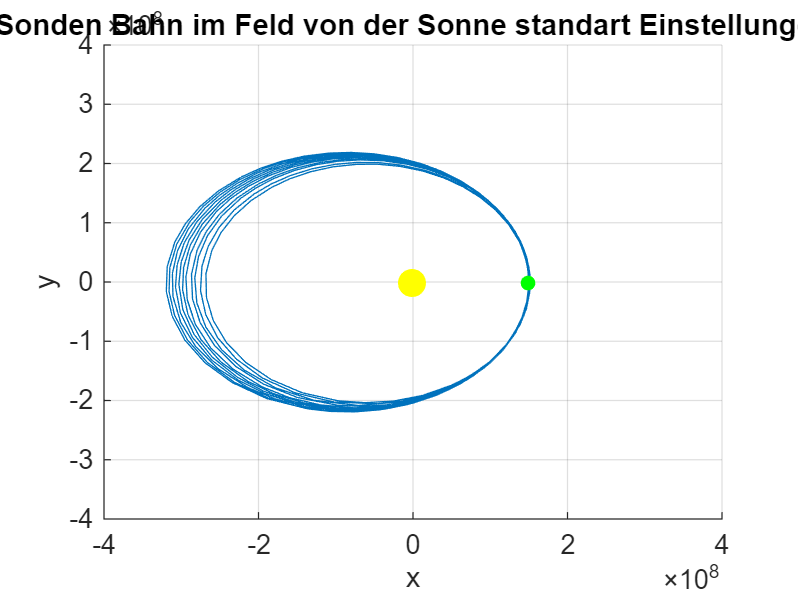

plotLimit = [-4e8, 4e8];

figure;
hold on;
plot(u(:,1), u(:,2));
plot(0,0, 'yo','MarkerSize',10,'MarkerFaceColor','y')
plot(pos0(1),pos0(2), 'go', 'MarkerSize',5,'MarkerFaceColor','g');
grid on;
title('Sonden Bahn im Feld von der Sonne standart Einstellungen');
xlabel('x');
ylabel('y');
xlim(plotLimit);
ylim(plotLimit);
hold off;

**Anpassung der ode45 Parameter**

Wie in unsere Übung, kann man die Parameter $RelTol$ für die Relative Toleranz und $AbsTol$ für die Absoulte Toleranz anpassen, um die Fehler beim Lösen der Differntial gleichung zu minimieren.

options = odeset('RelTol', 1e-13, 'AbsTol', 1e-16 * ones(size(pos0)));

**Erneutes Lösen und Visualiseren**

Lösen wir die Differntial Gleichung nun mit den neuen Einstellungen und Plotten diese wieder, kann man erkennen, das die Ungenauigkeiten verschwunden sind.

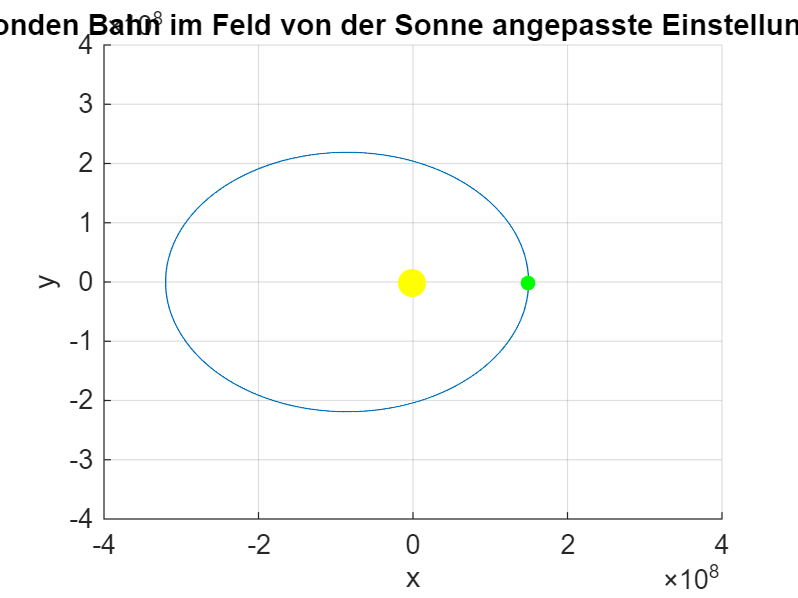

[t, u] = ode45(@(t, pos) calculateTrajectory(constants, pos), tSpan, pos0, options);

figure;
hold on;
plot(u(:,1), u(:,2));
plot(0,0, 'yo','MarkerSize',10,'MarkerFaceColor','y')
plot(pos0(1),pos0(2), 'go', 'MarkerSize',5,'MarkerFaceColor','g');
grid on;
title('Sonden Bahn im Feld von der Sonne angepasste Einstellungen');
xlabel('x');
ylabel('y');
xlim(plotLimit);
ylim(plotLimit);
hold off;

**Trajektorie1:**

Um die Ideale abschuss Geschwindigkeit zu bestimmen wird die $fminsearch$ Funktion benutzt um die $Trajektorie1$funktion mit Abbruch bedingung zu optimieren.

Optimiert wird dabei auf die geringste Geschwindigkeit mit kürzester Flugzeit. Sollte der Mars mit gegebener Geschwindigkeit im Simulationsfenster von 20 Jahren nicht erreichbar sein, wird die flugzeit auf $Inf$ gesetzt um die Geschwindigkeiten zu ignorien.

v_mars = fminsearch(@(v0)Trajektorie1(v0,constants),3.5)

v_mars = 3.4569

[~, flight_time] = Trajektorie1(v_mars, constants)

flight_time = 1.2871e+03

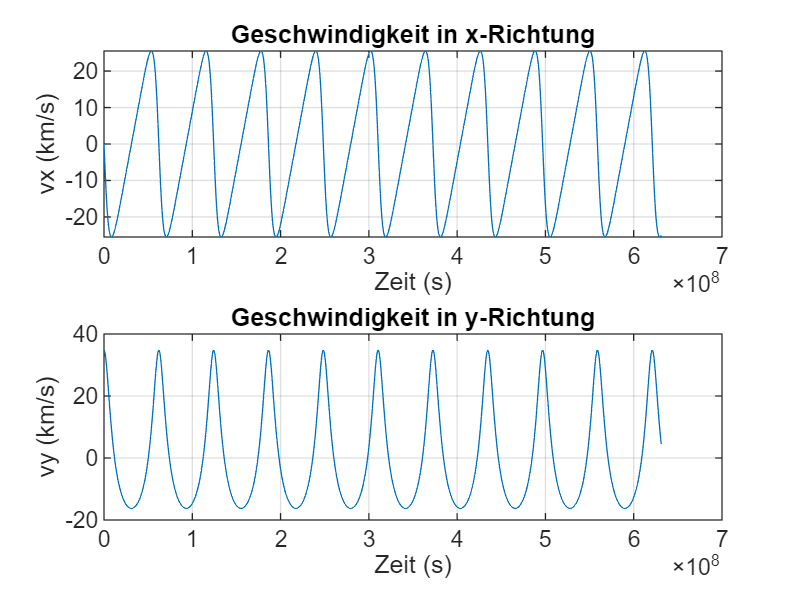


figure;
subplot(2,1,1);
plot(t, u(:,3));
xlabel('Zeit (s)');
ylabel('vx (km/s)');
title('Geschwindigkeit in x-Richtung');
grid on;

subplot(2,1,2);
plot(t, u(:,4));
xlabel('Zeit (s)');
ylabel('vy (km/s)');
title('Geschwindigkeit in y-Richtung');
grid on;

**Animation des Sonnensystems:**

pos0 = [constants.earthOrbitRadius + constants.earthRadius, 0, 0, v_mars + constants.earthVelocity];
[t, u] = ode45(@(t, pos) calculateTrajectory(constants, pos), tSpan, pos0, options);
%modelSolarSystemSonde(constants, t, u, flight_time);

**Probleme mit fminsearch:**

v0_array = linspace(3,10,10000);
abstand_array = zeros(length(v0_array), 1);

for i = 1:length(v0_array)
    v0 = v0_array(i);
    [abstand, flight_time] = Trajektorie1(v0,constants);
    abstand_array(i) = abstand;
end
%disp(v0_array);

  Columns 1 through 3276

    3.0000    3.0007    3.0014    3.0021    3.0028    3.0035    3.0042    3.0049    3.0056    3.0063    3.0070    3.0077    3.0084    3.0091    3.0098    3.0105    3.0112    3.0119    3.0126    3.0133    3.0140    3.0147    3.0154    3.0161    3.0168    3.0175    3.0182    3.0189    3.0196    3.0203    3.0210    3.0217    3.0224    3.0231    3.0238    3.0245    3.0252    3.0259    3.0266    3.0273    3.0280    3.0287    3.0294    3.0301    3.0308    3.0315    3.0322    3.0329    3.0336    3.0343    3.0350    3.0357    3.0364    3.0371    3.0378    3.0385    3.0392    3.0399    3.0406    3.0413    3.0420    3.0427    3.0434    3.0441    3.0448    3.0455    3.0462    3.0469    3.0476    3.0483    3.0490    3.0497    3.0504    3.0511    3.0518    3.0525    3.0532    3.0539    3.0546    3.0553    3.0560    3.0567    3.0574    3.0581    3.0588    3.0595    3.0602    3.0609    3.0616    3.0623    3.0630    3.0637    3.0644    3.0651    3.0658    3.0665    3.0672    

%disp(abstand_array)

   1.0e+08 *

       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
    5.9234
    6.0445
    6.1329
    5.3241
    1.9372
    1.9896
    5.2472
    3.8813
    5.5758
    5.9892
    2.4875
    2.5864
       Inf
    5.7321
    2.9701
    3.0964
    2.8113
    4.8956
    4.8731
    3.1938
    5.0585
    3.3458
    4.1958
    5.1346
    5.1871
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       Inf
       

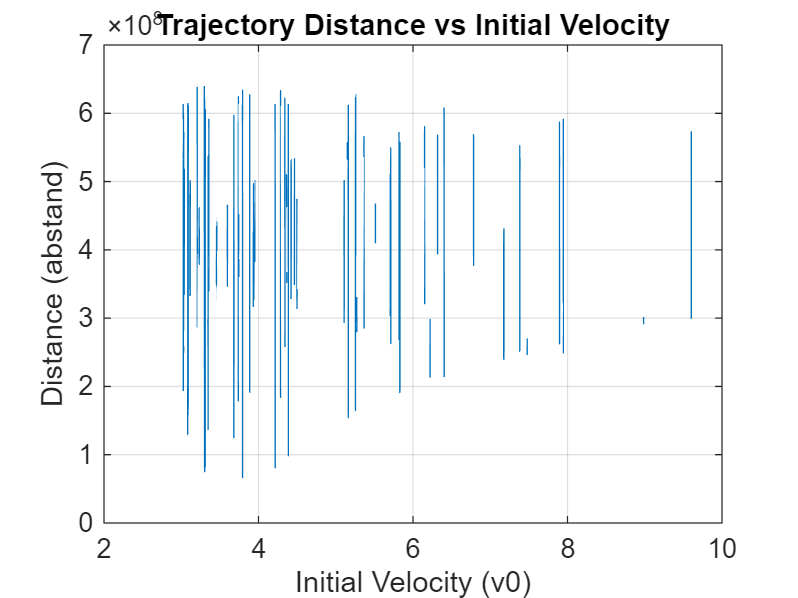


figure;
plot(v0_array, abstand_array);
xlabel('v0)');
ylabel('abstand');
grid on;

**Trajektorie 2:**

Trajektorie 2 wird ähnlich wie Trajektorie 1 gelöst, jdeoch das hier auf zwei parameter gleichzeitig optimiert wird.

Grundlegend unterscheiden sich Trajektorie 1 und 2 darin, das in der Ausgangs Situation der Geschwindigkeits vektor $\vec{v}$ anders aufgebaut ist:


$$\vec{v_1} = \pmatrix{0 \cr v_0}$$



$$\vec{v_2}=\pmatrix{v_0 * sin(\alpha) \cr v_0 * cos(\alpha)}$$


v_alpha = fminsearch(@(v0)Trajektorie2(v0,constants),[6,deg2rad(45)]);

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 204598198.548926 



Probiert man mit den standart Einstellungen von fminsearch ein Minimum zu finden, bekommt man einen Fehler und zwar das die $MaxFunEvals$ zu gering eingestellt sind.

options = optimset('MaxFunEvals', 10000, 'MaxIter', 1000);
v_alpha = fminsearch(@(v0)Trajektorie2(v0,constants),[6,deg2rad(45)]);

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 204598198.548926 



Stellt man die Einstellungen $MaxFunEvals$ und $MaxIter$ auf ein viel Faches von ihrem Standartwert, reicht dies immernoch nicht um eine Lösung zu erhalten.

**Minimumssuche mit fmincon:**

$fmincon$ ist eine Funktion in MATLAB, die zur *nichtlinearen Optimierung* verwendet wird. Sie minimiert eine skalare Zielfunktion unter Berücksichtigung von linearen und/oder nichtlinearen Gleichungs- und Ungleichungsbedingungen sowie von Grenzen für die Variablen.

lb = [3, 0];
ub = [10, pi];
options = optimoptions('fmincon', 'Algorithm', 'sqp', 'Display', 'iter');
v_alpha = fmincon(@(v0) Trajektorie2(v0, constants), [6, deg2rad(45)], [], [], [], [], lb, ub, [], options);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    1.000000e+12     0.000e+00     1.000e+00     0.000e+00     0.000e+00  

Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<

[~, flight_time] = Trajektorie2(v_alpha, constants)

flight_time = 1.0000e+12

fprintf("v_0: %.2f, Winkle: %.2f", v_alpha(1), v_alpha(2));

v_0: 6.00, Winkle: 0.79

Mit $fmincon$ findet man nun wieder stellen, bei denen sich die Sonde und der Mars treffen, jedoch wurden keine Ergebnisse erzielt, welche besser waren, als der tangenziale Abschuss

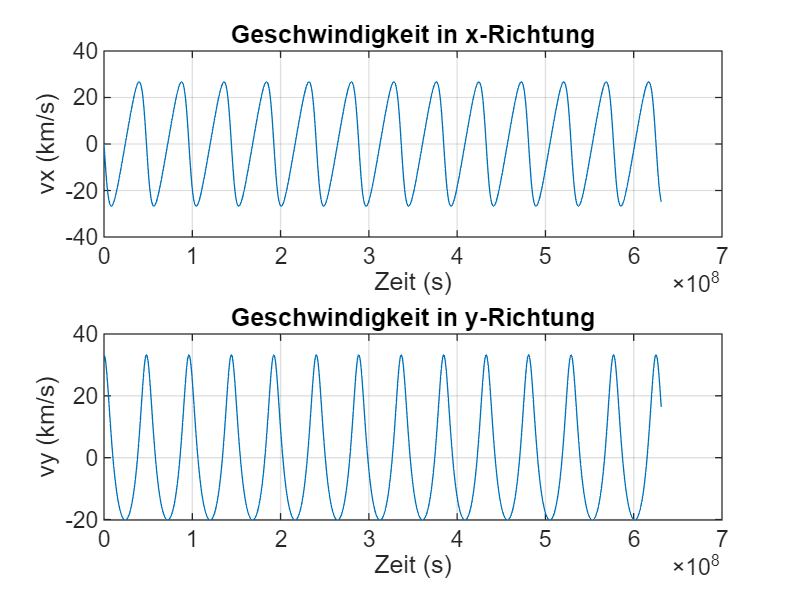

figure;
subplot(2,1,1);
plot(t, u(:,3));
xlabel('Zeit (s)');
ylabel('vx (km/s)');
title('Geschwindigkeit in x-Richtung');
grid on;

subplot(2,1,2);
plot(t, u(:,4));
xlabel('Zeit (s)');
ylabel('vy (km/s)');
title('Geschwindigkeit in y-Richtung');
grid on;

**Animation des Sonnensystems:**

options = odeset('RelTol', 1e-13, 'AbsTol', 1e-16 * ones(size(pos0)));
pos0 = [constants.earthOrbitRadius + constants.earthRadius, 0, v_alpha(1) * sin(v_alpha(2)), v_alpha(1) * cos(v_alpha(2)) + constants.earthVelocity];
[t, u] = ode45(@(t, pos) calculateTrajectory(constants, pos), tSpan, pos0, options);
%modelSolarSystemSonde(constants, t, u, flight_time);